S = 3;

NW = @(W,N,S) W.*N./(S + W);
FUNC = @(W,N,S) 4*(S+W).^3./(N.^4) - NW(W,N,S).^(-7/4).*exp(-sqrt(NW(W,N,S))) ...
    .*(S./(4*W).*(2*sqrt(NW(W,N,S))+7 ) -1);
DFUNC = @(W,N,S) 12*(S+W).^2./(N.^4) + (S./(4*N.*W.^2)).^2.*exp(-sqrt(NW(W,N,S)))...
    .*NW(W,N,S).^(1/4).*( 32*(S+W).*sqrt(NW(W,N,S)) + 4*N.*W + 77*(S+W) );



N = 32:1024;


S = 3:6;
L = numel(S);
NL = repmat(N, L, 1);
WL = 0*NL;

for i = 1:L

    W = 0.25*S(i)*ones(size(NL(i,:)));
    func = @(w) FUNC(w,NL(i,:),S(i));
    dfunc = @(w) DFUNC(w,NL(i,:),S(i));
    [WL(i,:), res] = NewtonsMethod1D(func, dfunc, 0, W, 1e-5, 300);

    disp([num2str(i) ' residual = ' num2str(res)]);

end

1 residual = -1.0083e-07 -1.1286e-07 -1.2498e-07 -1.3707e-07 -1.4903e-07 -1.6074e-07 -1.7211e-07 -1.8307e-07 -1.9354e-07 -2.0348e-07 -2.1283e-07 -2.2157e-07 -2.2966e-07 -2.3709e-07 -2.4385e-07 -2.4994e-07 -2.5537e-07 -2.6014e-07 -2.6427e-07 -2.6777e-07 -2.7068e-07   -2.73e-07 -2.7477e-07 -2.7601e-07 -2.7676e-07 -2.7703e-07 -2.7686e-07 -2.7628e-07 -2.7531e-07 -2.7398e-07 -2.7231e-07 -2.7034e-07  -2.681e-07 -2.6559e-07 -2.6285e-07  -2.599e-07 -2.5676e-07 -2.5346e-07    -2.5e-07 -2.4641e-07  -2.427e-07  -2.389e-07 -2.3501e-07 -2.3104e-07 -2.2703e-07 -2.2296e-07 -2.1886e-07 -2.1473e-07 -2.1059e-07 -2.0645e-07  -2.023e-07 -1.9816e-07 -1.9404e-07 -1.8994e-07 -1.8587e-07 -1.8183e-07 -1.7783e-07 -1.7386e-07 -1.6994e-07 -1.6607e-07 -1.6225e-07 -1.5848e-07 -1.5477e-07 -1.5112e-07 -1.4752e-07 -1.4398e-07 -1.4051e-07 -1.3709e-07 -1.3374e-07 -1.3045e-07 -1.2723e-07 -1.2407e-07 -1.2097e-07 -1.1794e-07 -1.1497e-07 -1.1206e-07 -1.0921e-07 -1.0643e-07 -1.0371e-07 -1.0105e-07 -9.8453e-08 -9.5914e-08 -9.

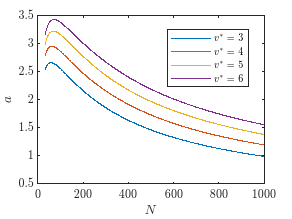


NL = NL.';
WL = WL.';

figure;
plot(NL, WL);
xlabel('$N$');
ylabel('$a$');
xlim([0 1000]);
legend('$v^*=3$', '$v^*=4$', '$v^*=5$', '$v^*=6$', 'Location',"best")
save_fig_tikz("ExtensionSize")

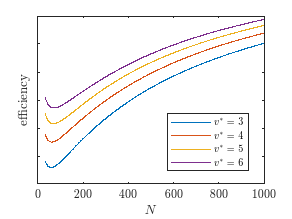


figure;
plot(NL, 100*S./(S+WL));
xlabel('$N$');
ylabel('efficiency');
xlim([0 1000]);
ytickformat('percentage');
legend('$v^*=3$', '$v^*=4$', '$v^*=5$', '$v^*=6$', 'Location',"best")

save_fig_tikz("ExtensionEfficiency")